# SV models

- Prepare stochastic volatility models

- Identify a SVAR using Cholesky

- Checking TV features of sigma in estimation/IRF/forecast



clear
close all
rehash path

addpath ../sandbox
addpath ../bear


## Convenience functions

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];


## Prepare data and a reduced-form model

inputTbx = tablex.fromCsv("SV.csv");

estimStart = datex.q(1971,2);
estimEnd = datex.q(2020,1);
estimSpan = datex.span(estimStart, estimEnd);

meta = model.Meta( ...
    endogenous=["YER", "HICSA", "STN"], ...
    units="", ...
    exogenous=[], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    ...
    identificationHorizon=20, ...
    shockConcepts=["DEM", "SUP", "POL"] ...
);

dataH = model.DataHolder(meta, inputTbx);


## Stochastic-volatiliy models

Standard (CogleySargentSV)


estimatorR1 = estimator.CogleySargentSV(meta);

modelR1 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR1 ...
    , stabilityThreshold=Inf ...
);
modelR1.Estimator.Settings

ans =   CogleySargentSV with properties:

                              Burnin: 0
                           Exogenous: [3×1 logical]
                      BlockExogenous: 0
                      Autoregression: [3×1 double]
                             Lambda1: 0.1000
                             Lambda2: 0.5000
                             Lambda3: 1
                             Lambda4: [3×1 double]
                             Lambda5: 1.0000e-03
    HeteroskedasticityAutoRegression: 1
             HeteroskedasticityShape: 1.0000e-03
             HeteroskedasticityScale: 1.0000e-03


Random inertia


estimatorR2 = estimator.RandomInertiaSV(meta);

modelR2 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR2 ...
    , stabilityThreshold=Inf ...
);
modelR2.Estimator.Settings

ans =   RandomInertiaSV with properties:

    HeteroskedasticityAutoRegressionVariance: 0.0100
                                      Burnin: 0
                                   Exogenous: [3×1 logical]
                              BlockExogenous: 0
                              Autoregression: [3×1 double]
                                     Lambda1: 0.1000
                                     Lambda2: 0.5000
                                     Lambda3: 1
                                     Lambda4: [3×1 double]
                                     Lambda5: 1.0000e-03
            HeteroskedasticityAutoRegression: 1
                     HeteroskedasticityShape: 1.0000e-03
                     HeteroskedasticityScale: 1.0000e-03


large models (Carriero) 


estimatorR3 = estimator.CarrieroSV(meta);

modelR3 = model.ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR3 ...
    , stabilityThreshold=Inf ...
);
modelR3.Estimator.Settings

ans =   CarrieroSV with properties:

                              Burnin: 0
                           Exogenous: [3×1 logical]
                      BlockExogenous: 0
                      Autoregression: [3×1 double]
                             Lambda1: 0.1000
                             Lambda2: 0.5000
                             Lambda3: 1
                             Lambda4: [3×1 double]
                             Lambda5: 1.0000e-03
    HeteroskedasticityAutoRegression: 1
             HeteroskedasticityShape: 1.0000e-03
             HeteroskedasticityScale: 1.0000e-03


## Indentify a SVAR using Cholesky (without reordering)

Standard


identChol = identifier.Cholesky(order=[]);

modelS1 = model.Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();
info1 = modelS1.presample(1000);


 Presampling model.Structural (CogleySargentSV) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [39×1 double]
                     F: [3×3 double]
                     L: {196×1 cell}
                   phi: [0.0871 0.0011 0.1180]
              sigmaAvg: [9×1 double]
                  sbar: [3×1 double]
              lambda_t: {196×1 cell}
               sigma_t: {196×1 cell}
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [3×3 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.6167    0.0259    0.0497
   -0.0762    0.7321    0.0850
   -0.0151    0.0062    1.1775
    0.0772   -0.0223    0.0122
    0.0159    0.0708    0.0441
    0.0014    0.0070   -0.1567
    0.0377    0.0069   -0.0056
    0.0263    0.0657   -0.0066
    0.0070   -0.0071   -0.0454
    0.0007    0.0024   -0.0072


modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.6167    0.0259    0.0497
   -0.0762    0.7321    0.0850
   -0.0151    0.0062    1.1775
    0.0772   -0.0223    0.0122
    0.0159    0.0708    0.0441
    0.0014    0.0070   -0.1567
    0.0377    0.0069   -0.0056
    0.0263    0.0657   -0.0066
    0.0070   -0.0071   -0.0454
    0.0007    0.0024   -0.0072


Random inertia


modelS2 = model.Structural(reducedForm=modelR2, identifier=identChol);
modelS2.initialize();
info2 = modelS2.presample(1000);


 Presampling model.Structural (RandomInertiaSV) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS2.Presampled{1}

ans = struct with fields:
                  beta: [39×1 double]
                 omega: 10000
                     F: [3×3 double]
                     L: {196×1 cell}
                   phi: [0.1044 0.0471 0.1302]
              sigmaAvg: [9×1 double]
                 gamma: [0.9649 0.8295 0.9779]
                  sbar: [3×1 double]
              lambda_t: {196×1 cell}
               sigma_t: {196×1 cell}
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


modelS2.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [3×3 double]


modelS2.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.4136    0.0070    0.0736
   -0.0994    0.7418    0.0738
   -0.0456    0.0191    1.1360
    0.0756   -0.0135    0.0261
    0.0781    0.0817   -0.0058
    0.0515   -0.0021   -0.1242
    0.0283    0.0144   -0.0191
   -0.0074    0.0881   -0.0025
    0.0013   -0.0111   -0.0287
   -0.0149    0.0040    0.0065


modelS2.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.4136    0.0070    0.0736
   -0.0994    0.7418    0.0738
   -0.0456    0.0191    1.1360
    0.0756   -0.0135    0.0261
    0.0781    0.0817   -0.0058
    0.0515   -0.0021   -0.1242
    0.0283    0.0144   -0.0191
   -0.0074    0.0881   -0.0025
    0.0013   -0.0111   -0.0287
   -0.0149    0.0040    0.0065


Large models


modelS3 = model.Structural(reducedForm=modelR3, identifier=identChol);
modelS3.initialize();
info3 = modelS3.presample(1000);


 Presampling model.Structural (CarrieroSV) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS3.Presampled{1}

ans = struct with fields:
                  beta: [39×1 double]
                     F: [3×3 double]
                     L: {196×1 cell}
                   phi: 1.7076
              sigmaAvg: [9×1 double]
                  sbar: [3×1 double]
              lambda_t: {196×1 cell}
               sigma_t: {196×1 cell}
    IdentificationDraw: [1×1 struct]
                     D: [3×3 double]


modelS3.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {20×1 cell}
        C: {20×1 cell}
    Sigma: [3×3 double]


modelS3.Presampled{1}.IdentificationDraw.A{1,1}

ans =     0.6199    0.0906    0.2182
    0.0329    0.5473    0.7052
   -0.0362    0.0690    1.1309
    0.0776   -0.0211    0.0693
   -0.0040    0.2027   -0.0558
    0.0075   -0.0564   -0.2951
    0.0053    0.0023    0.0395
    0.0183    0.0967   -0.1277
    0.0228    0.0162    0.0309
   -0.0104    0.0132   -0.0156


modelS3.Presampled{1}.IdentificationDraw.A{2,1}

ans =     0.6199    0.0906    0.2182
    0.0329    0.5473    0.7052
   -0.0362    0.0690    1.1309
    0.0776   -0.0211    0.0693
   -0.0040    0.2027   -0.0558
    0.0075   -0.0564   -0.2951
    0.0053    0.0023    0.0395
    0.0183    0.0967   -0.1277
    0.0228    0.0162    0.0309
   -0.0104    0.0132   -0.0156


## Impulse responses

Standard

respTbx1 = modelS1.simulateResponses();
respTbx1 = tablex.apply(respTbx1, prctileFunc);
respTbx1 = tablex.flatten(respTbx1);

respTbx1

respTbx1 = 24×9 timetable
     Time                      YER___DEM                                  YER___SUP                                 YER___POL                                   HICSA___DEM                             HICSA___SUP                            HICSA___POL                             STN___DEM                             STN___SUP                           STN___POL          
    _______    _________________________________________    _____________________________________    ________________________________________    _________________________________________    ________________________________    ______________________________________    ________________________________

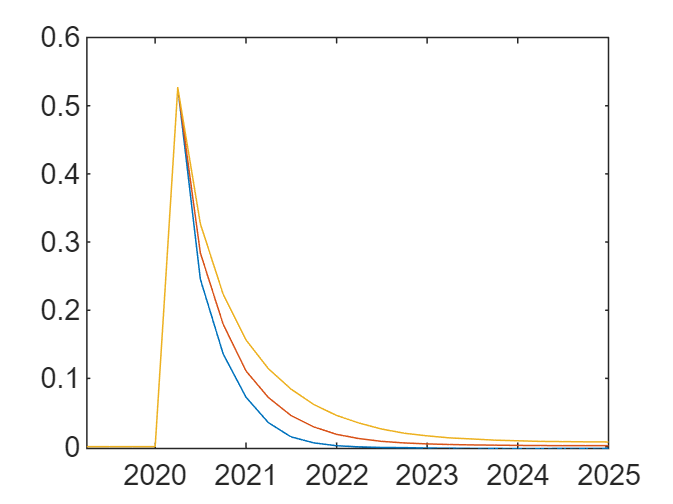

ans =   3×1 Line array:

  Line
  Line
  Line



tablex.plot(respTbx1,"YER___DEM")

Random-inertia

respTbx2 = modelS2.simulateResponses();
respTbx2 = tablex.apply(respTbx2, prctileFunc);
respTbx2 = tablex.flatten(respTbx2);

respTbx2

respTbx2 = 24×9 timetable
     Time                      YER___DEM                                  YER___SUP                                YER___POL                                HICSA___DEM                             HICSA___SUP                            HICSA___POL                             STN___DEM                             STN___SUP                           STN___POL          
    _______    _________________________________________    _____________________________________    _____________________________________    ________________________________________    ________________________________    ______________________________________    ________________________________   

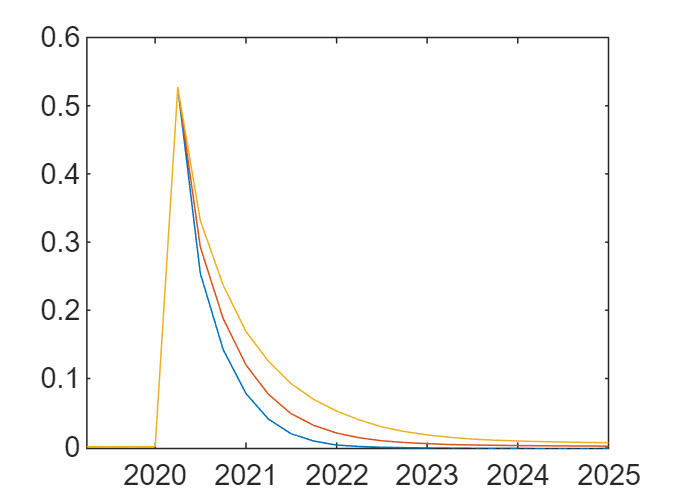

ans =   3×1 Line array:

  Line
  Line
  Line



tablex.plot(respTbx2,"YER___DEM")

Large models

respTbx3 = modelS3.simulateResponses();
respTbx3 = tablex.apply(respTbx3, prctileFunc);
respTbx3 = tablex.flatten(respTbx3);

respTbx3

respTbx3 = 24×9 timetable
     Time                    YER___DEM                                 YER___SUP                                 YER___POL                              HICSA___DEM                          HICSA___SUP                         HICSA___POL                          STN___DEM                           STN___SUP                          STN___POL          
    _______    ______________________________________    ______________________________________    _____________________________________    ___________________________________    ________________________________    ________________________________    ________________________________    ____________________

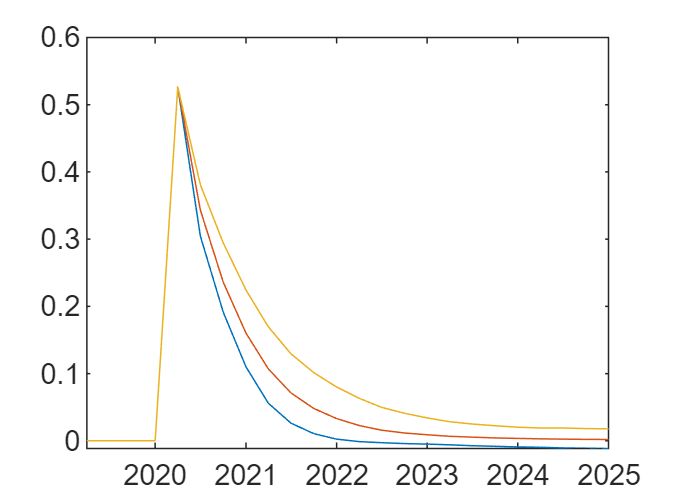

ans =   3×1 Line array:

  Line
  Line
  Line



tablex.plot(respTbx3,"YER___DEM")

## Unconditional forecast 


fcastStart = datex.shift(modelS1.Meta.EstimationEnd, -10);
fcastEnd = datex.shift(modelS1.Meta.EstimationEnd, 0);
fcastSpan = datex.span(fcastStart, fcastEnd);


Standard

fcastTbx1 = modelS1.forecast(fcastSpan);
fcastPrctileTbx1 = tablex.apply(fcastTbx1, prctileFunc);
fcastPrctileTbx1 = tablex.flatten(fcastPrctileTbx1);

fcastTbx1

fcastTbx1 = 15×6 timetable
     Time           YER             HICSA             STN           resid_YER       resid_HICSA       resid_STN  
    _______    _____________    _____________    _____________    _____________    _____________    _____________

    2016-Q3    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2016-Q4    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q1    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q2    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double

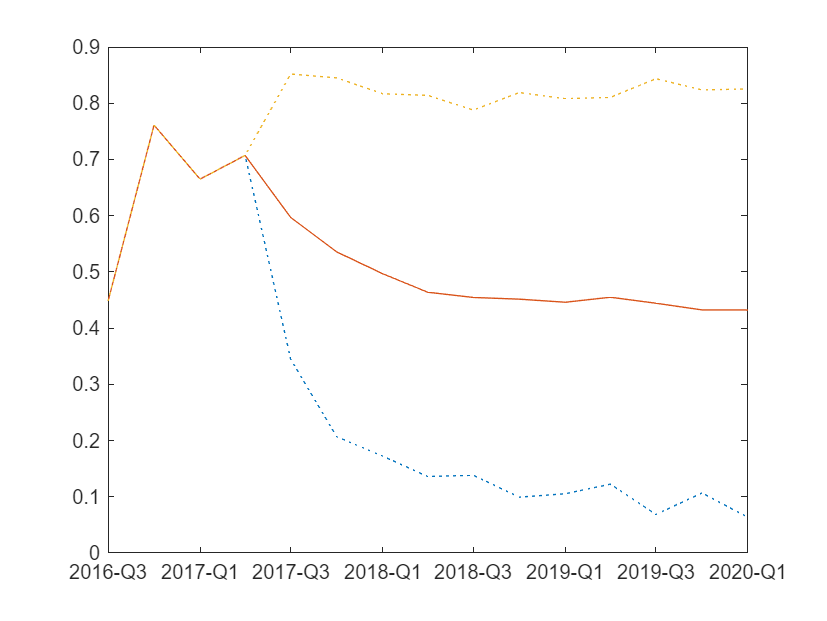


tablex.plot( ...
    fcastPrctileTbx1, "YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);

Random inertia

fcastTbx2 = modelS2.forecast(fcastSpan);
fcastPrctileTbx2 = tablex.apply(fcastTbx2, prctileFunc);
fcastPrctileTbx2 = tablex.flatten(fcastPrctileTbx2);

fcastTbx2

fcastTbx2 = 15×6 timetable
     Time           YER             HICSA             STN           resid_YER       resid_HICSA       resid_STN  
    _______    _____________    _____________    _____________    _____________    _____________    _____________

    2016-Q3    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2016-Q4    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q1    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q2    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double

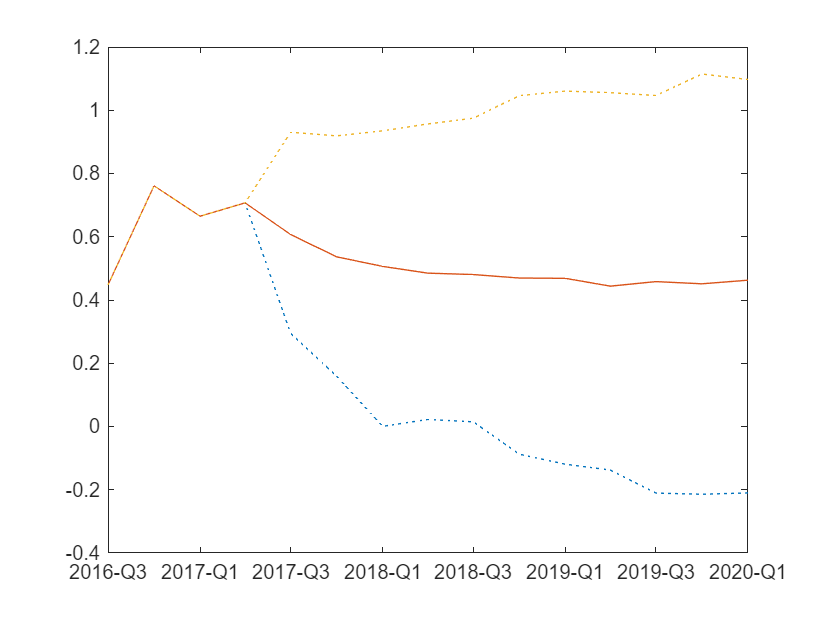


tablex.plot( ...
    fcastPrctileTbx2, "YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);

Large models

fcastTbx3 = modelS3.forecast(fcastSpan);
fcastPrctileTbx3 = tablex.apply(fcastTbx3, prctileFunc);
fcastPrctileTbx3 = tablex.flatten(fcastPrctileTbx3);

fcastTbx3

fcastTbx3 = 15×6 timetable
     Time           YER             HICSA             STN           resid_YER       resid_HICSA       resid_STN  
    _______    _____________    _____________    _____________    _____________    _____________    _____________

    2016-Q3    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2016-Q4    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q1    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double
    2017-Q2    1×1000 double    1×1000 double    1×1000 double    1×1000 double    1×1000 double

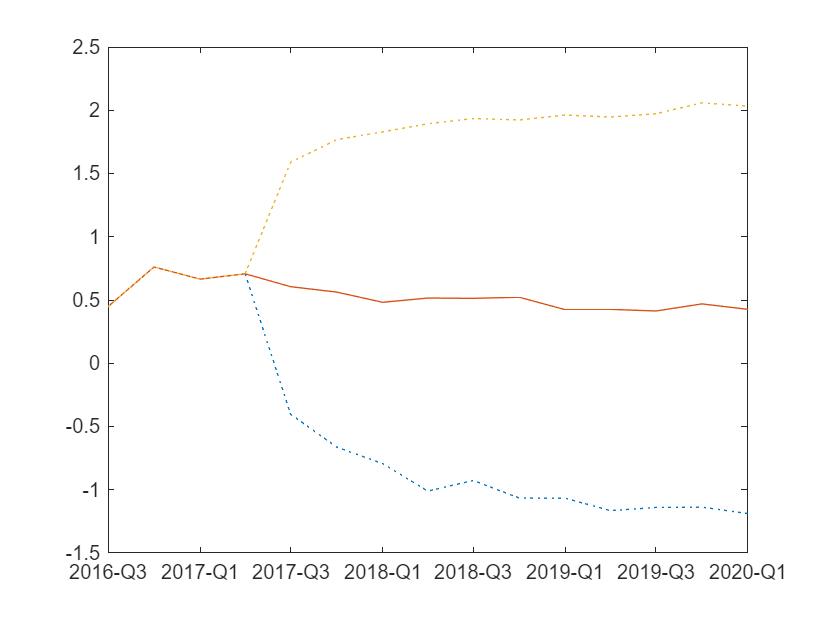


tablex.plot( ...
    fcastPrctileTbx3, "YER", ...
    plotSettings={{"lineStyle"}, {":"; "-"; ":"}} ...
);